# Bouncing Ball Simulation

clear;clc;

height = 15;
y0 = [height;0];
e = 0.75;
ball_radius = 0.5;
ground = -ball_radius;

## Simulate

n = 10;
tstart = 0;
deltat = 5;
tsim = [];
ysim = [];

for k = 1:n
    [t,y] = one_bounce(tstart,deltat,y0,ground);
    
    % This interpolation is completely a guess to make the animaton look more realistic
    tq = linspace(t(1),t(end),height*3*e^k);
    
    yq = interp1(t,y,tq);
    tsim = [tsim; tq(1:end-1)'];
    ysim = [ysim; yq(1:end-1,:)];
    
    tstart = t(end);
    y0 = [y(end,1) -e*y(end,2)];
end

## Animate

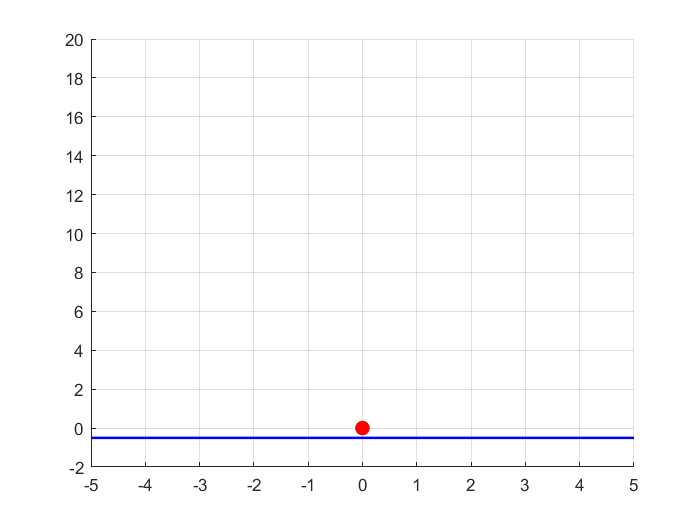

figure(1);
for k=1:size(ysim,1)
    ypos = ysim(k,1)+ball_radius;
    grid on;
    hold on;
    h1 = line([-5 5],[ground ground], "LineWidth", 1.5, 'Color', 'blue');
    h2 = plot(0,ypos,'.','MarkerSize',30,'Color','red');
    axis([-5 5 -2 20]);
    drawnow;
    if k~=size(ysim,1)
        delete(h1);
        delete(h2);
    end
end

## Plots

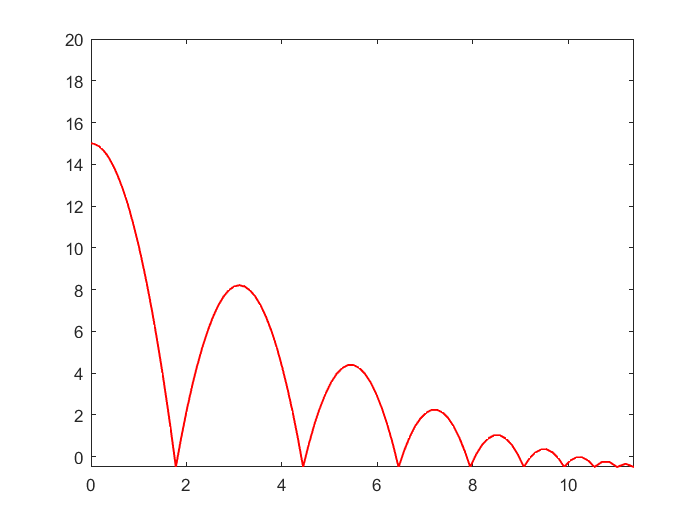

figure(2);
plot(tsim,ysim(:,1),'k','LineWidth',1,'Color','red');
axis([0 tsim(end) ground 20]);

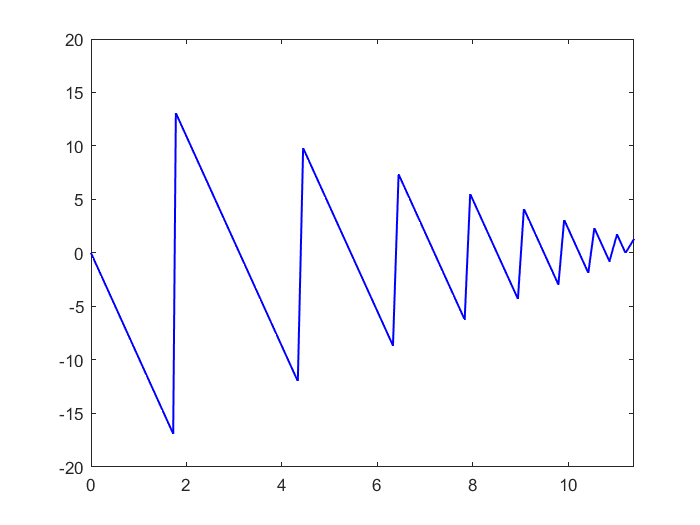

figure(3);
plot(tsim,ysim(:,2),'k','LineWidth',1,'Color','blue');
axis([0 tsim(end) -20 20]);